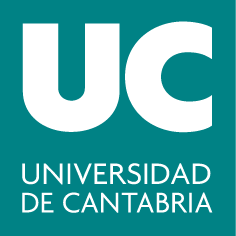

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **3. Funciones de una variable**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Funciones

Una** función** es un programa con una interfaz de comunicación con el exterior mediante argumentos de entrada y de salida. Las funciones deben guardarse en un fichero con el mismo nombre que la propia función y extensión `.m`. Las funciones en MATLAB tienen la siguiente estructura:

Para crear una nueva función: Home -> New -> Function

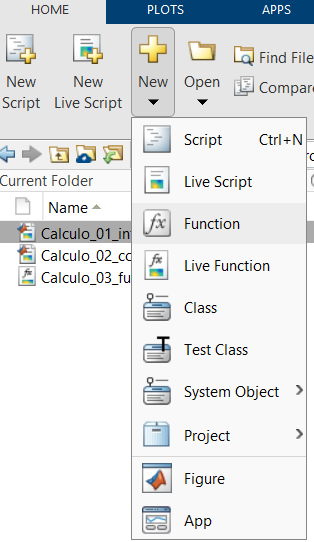

**Ejemplo**: Función que halla el área ($$A$$) de un círculo: 

Para que MATLAB reconozca la función que acabamos de crear tenemos dos opciones: 

- Situarnos en la misma ruta (directorio) en la que hayamos salvado la función. Esta opción sólo será válida mientras permanezcamos en el mismo directorio.

- Utilizar la orden `addpath` para incluir en memoria la ruta (directorio) en la que hayamos guardado la función.  

- Una vez hecho esto, podremos volver a movernos libremente por el árbol de directorios del equipo.

A partir de este momento, podremos llamar a la función desde la línea de comandos:

- A menudo, funciones tan sencillas como la que acabamos de crear (que devuelven el resultado de una única orden) se definen directamente en la línea de comandos o incluso en mitad de un script** funciones anónimas** o `function handle`). La forma de hacerlo es la siguiente:

**Ejemplo: **Función que eleva un número dado al cuadrado:	

eleva_cuad = @(x)  x^2;  % defino funcion
class(eleva_cuad)  % funcion tipo handle
x = eleva_cuad(4)  % elevo 4 al cuadrado

A partir de este momento ya podremos definir en MATLAB funciones de una variable real. 

Ejercicio: Define la función $$f(x) = x^2 + 2$$ como una función anónima:

% escribe aquí el código:




Solución:

f = @(x)  x^2 + 2; 

Para evaluar dicha función en un determinado $$x$$ sólo tendremos que darle el valor deseado al argumento de entrada $$x$$. Por ejemplo, para evaluar $$f$$ en el punto $$x=-\pi/2$$ bastaría con hacer lo siguiente:

f(-pi/2)

Si quisiéramos evaluar $$f$$ en varios puntos a la vez bastaría con utilizar como argumento de entrada un vector (en lugar de un único número). Sin embargo, fíjate que para poder operar con vectores, debemos modificar ligeramente la función$ $f$$ antes:

f_vec = @(x)  x.^2 + 2;     % redefino la funcion para que opere con vectores
f_vec(-10:10)               % evaluo la funcion en {-10,-9,-8,...,8,9,10}

### Gráficos

Llegados a este punto podemos ya **plotear** (representar gráficamente) funciones de una variable real. La función básica de dibujo en MATLAB es `plot`, que permite representar pares de puntos $$(x, y)$$.

x = -10:10;
y = x;
plot(x, y)  % recta y=x en el intervalo x=[-10,10]

Si le pasamos un único argumento de entrada, la función `plot` entiende que nos referimos al eje de ordenadas, y asigna valores naturales (comenzando en 1) al eje de abscisas.

plot(y)  

Para etiquetar los ejes se utilizan los comandos `xlabel('Eje x')` y `ylabel('Eje y')`. Para agregar un título a la figura, se usa el comando `title('Título')`. Para mostrar la cuadrícula en la gráfica, se emplea el comando `grid on`.

**Ejercicio**: Representa en rojo la parábola $$f(x) = x^2 - 50$$ en el intervalo $$[-20, 15]$$. Etiqueta el eje de abscisas como "x", el de ordenadas como "y" y pon un título al gráfico. Dibuja una cuadrícula en el fondo.

% escribe aquí el código:



Solución:

f = @(x)  x.^2 -50;
plot(-20:15, f(-20:15), 'r')
xlabel('x')  % etiqueta eje x
ylabel('y')  % etiqueta eje y
title('Parabola')  % titulo figura
grid on  % cuadricula en el fondo

Como ya hemos visto, `hold on `se utiliza para seguir dibujando en la última ventana gráfica que esté activa. Esto nos permitirá superponer la gráfica de dos o más funciones en una única figura. Con el comando `legend` podremos además añadir una leyenda, que siempre resulta muy útil.

Ejemplo: Representa en azul la función $$f(x) = \frac{x^2}{4}$$ y en rojo la función$ $g(x) = \sqrt{x^2}$$ en el intervalo $$[-10, 10]$$. Dibuja una leyenda que identifique apropiadamente ambas funciones. Etiqueta los ejes y pon un título al gráfico. Por último, dibuja una cuadrícula en el fondo.

f = @(x)  x.^2/4;  % defino f
g = @(x)  sqrt(x.^2);  % defino g

vec_abscisas = -10:10;  % defino dominio

plot(vec_abscisas, f(vec_abscisas), 'b')
hold on  % permanezco en la misma ventana grafica
plot(vec_abscisas, g(vec_abscisas), 'r')

legend('y=x^2/4', 'y=sqrt(x^2)', 'Location', 'northeast')  % defino leyenda

xlabel('eje x'), ylabel('eje y'), title('Dos funciones')
grid on  % rejilla de fondo
hold off

### **Variables y funciones simbólicas**

#### **Variables simbólicas**

MATLAB permite trabajar con variables  simbólicas, es decir, variables genéricas que, en principio, no tienen porqué tomar un valor concreto (piensa en las incógnitas de cualquier ecuación). Para ello, tenemos que tener instalado el paquete "Symbolic Math Toolbox".

Apps -> Get More Apps -> Symbolic Math Toolbox -> Install

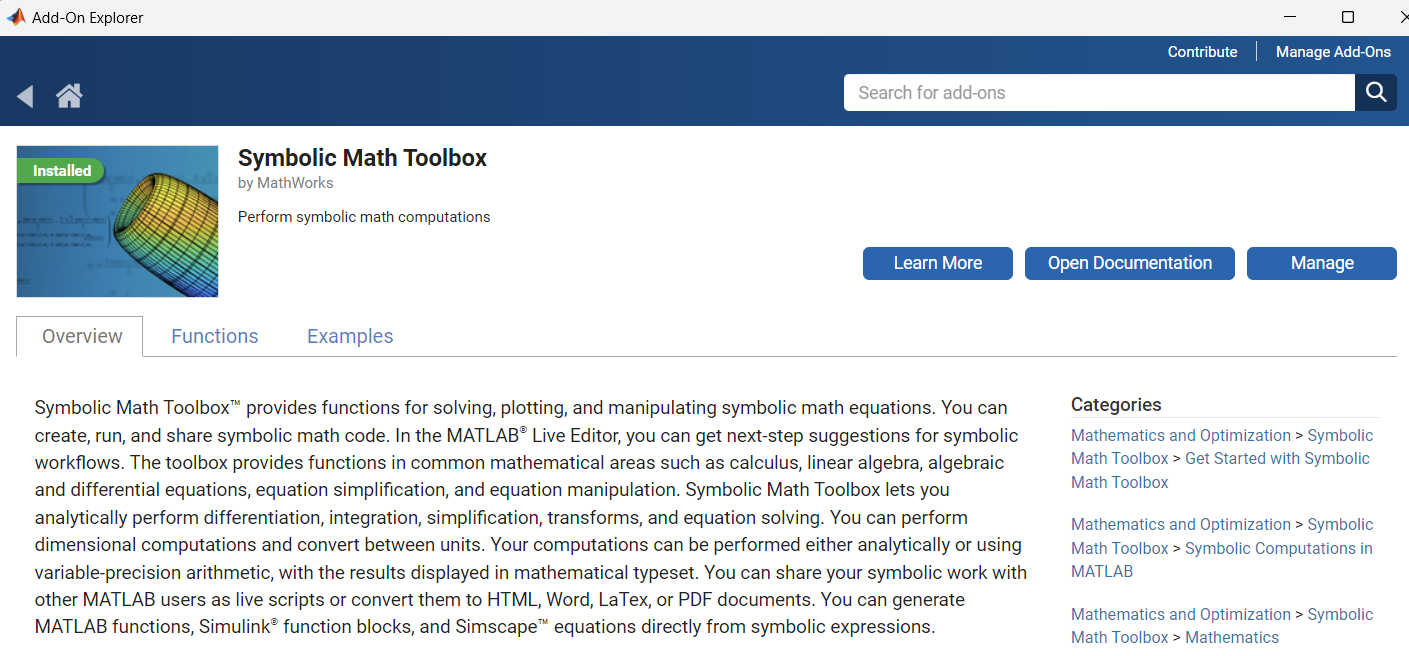

Para crear una variable simbólica se utiliza el comando syms:

Una vez definida, podemos crear expresiones simbólicas que dependen de `x`.

clearvars % limpiamos la memoria
syms x
eq = x^2 + 5;  % ecuacion que depende de x

Prestamos atención al espacio de trabajo:

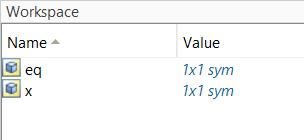

ni `x` ni `eq` tienen valores numéricos asignados. La forma de obligar a que una variable simbólica tome un determinado valor es la siguiente:

v = subs(eq, x, 3)  % forzamos a que x tome el valor 3 en la expresion 'eq'

Aunque `v` puede parecer un número, en realidad es una variable simbólica a la que se le ha asignado un valor numérico. 

class(v)

Para convertir una variable simbólica a un número real, se utiliza el comando `double:`

v_num = double(v)

Ahora en el espacio de trabajo tenemos:

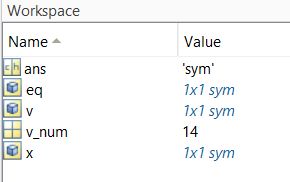

La variable v_num tiene un valor (14), es un número para MATLAB.

#### Funciones simbólicas

Para definir una función de variable simbólica:

clearvars % limpiamos la memoria
syms x
f(x) =  x^2+5; % definimos f(x)
class(f)

Hemos definido $f(x)$ como una función simbólica, `symfun`. Esto nos permite evaluar la función en cualquier punto directamente, sin necesidad de usar el comando `subs`.

f(3) % valor de la funcion f en x=3
f([1:10]) % vector de valores simbólicos

Se pueden definir varias variables simbólicas a la vez, así como el tipo exacto de variable con la que queremos trabajar:

De este modo resulta muy fácil definir, en modo simbólico, funciones de una variable real en MATLAB. Para representar gráficamente este tipo de funciones se utiliza el comando `fplot`.

**Ejemplo**: Representa la función $$f(x) = sen(x) + 3x + \frac{8}{x+1}$$ en el intervalo $$[-4, 4]$$.

syms x real  % defino 'x' como variable simbolica real
y(x) = sin(x) + 3*x + 8/(x+1) ; % defino f(x)
fplot(y, [-4, 4],'r')  % represento f(x) en [-4, 4]
grid on

#### Funciones implícitas

Una **función implícita** describe una relación entre variables que no está resuelta explícitamente para una de las variables. Por ejemplo, la ecuación de un círculo $ x^2 + y^2 - 1 = 0$ define una relación implícita entre $x$ e $y$.

MATLAB permite graficar funciones implícitas utilizando la función `fimplicit` en combinación con el cálculo simbólico para definir y manipular estas funciones.

Primero, definimos las variables simbólicas

clearvars
syms x y real


Luego, definimos la ecuación implícita como una expresión simbólica:

ecuacion = x^2 + y^2 - 1;

Utilizamos `fimplicit` para graficar la función implícita:

fimplicit(ecuacion)
title('Círculo de radio 1')
xlabel('x')
ylabel('y')
grid on

En este caso, el gráfico del círculo parece una elipse. Para mejorarlo:

axis equal

### Ejercicios propuestos

1. Define las siguientes funciones (como funciones simbólicas) de una variable y halla el valor (numérico) en el punto$ $x=\pi$$.

- 
$$ $f(x) = \frac{x}{1+|x|}$$$
		

- 
$$ $f(x) = \frac{e^x + e^{-x}}{2}$  $$


- 
$$$f(x) = senh(x)$$$


- 
$$$\;g_1(x) = f_1(f_2(x))$  y $\;g_2(x) = f_2(f_1(x))$, con $f_1(x) = x^2+1$ y $\;f_2(x) = \frac{2}{x}$$$
	

% escribe aquí el código:





Solución:

soluciones(1)

2. Halla, gráficamente, el punto en el que se cortan las funciones $$f(x)=\frac{2}{x}$$ y $$g(x)=\sqrt{x^2-3}$$. Para ello, representa en una única figura$ $f$$ (en negro) y$ $g$$ (en rojo). Elige el intervalo adecuado.  Pon una leyenda que identifique cada curva y un título a la figura.

% escribe aquí el código:




Solución:

soluciones(2)

3. Dibuja, en una misma gráfica y en color verde, las circunferencias  $$x^2 + y^2 - 4x = 1$$ (con línea continua) y$ $x^2 + y^2 + 2y = 9$$ (con línea discontinua). Pon una leyenda adecuada. 

% escribe aquí el código:




Solución:

soluciones(3)

4. A partir de los gráficos necesarios, estudia el dominio, imagen y el carácter par/impar de las siguientes funciones:

- 
$$ $\cos(x^2)$$$


-  
$$$\cos^2(x)$$$


- 
$$ $\cos^2(x^2)$$$


-  
$$$\sqrt{x^3}$     $$
  				

% escribe aquí el código:




Solución:

soluciones(4)

### Resumen

- **Definir una función (M-function)**

- **Función anónima**:

- **Definir variable simbólica**: 

- `subs:  `Sustituir en expresión

- `double: `Convertir variable simbólica a número real

- **Definir función simbólica**:

**Gráficos**

- `plot(x, y): `graficar y(x), siendo x e y - dos vectores

- `fplot(f(x),[x1 x2])`: graficar$ f(x) $ en el intervalo [x1, x2], $ f(x) $ puede ser una función simbólica o anónima.

- `fimplicit(ecuacion, [x1 x2 y1 y2]): `graficar $f(x,y) = 0$ (función implícita)

- `xlabel('Eje x'), ylabel('Eje y'): `etiquetar los ejes.

- `title('Título'): `añadir título

- `grid on: `activa la rejilla en el fondo

- `legend('Descripción 1', 'Descripción 2'): `agregar leyenda

- `axis equal: `Establecer la misma longitud para las unidades de datos a lo largo de cada eje.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        % Ejercicio 1:
        fprintf("Ejercicio 1:\n ");
        syms x
        f(x) = x/(1+abs(x))
        f1 = double(f(pi))
        f(x) = (exp(x) + exp(-x))/2
        f2 = double(f(pi))
        f(x) = sinh(x)
        f3 = double(f(pi))
        f_1(x) = x^2+1;
        f_2(x) = 2/x;
        g_1(x) = f_1(  f_2 (x) )

        g1 = double(g_1(pi))
        g_2(x) = f_2(  f_1 (x) )
        g2 = double(g_2(pi))

    case 2
        % Ejercicio 2:
        fprintf("Ejercicio 2:\n");
        syms x
        f(x) = 2/x
        g(x) = sqrt(x^2-3)
        fplot(f,[1.5,3],'k')
        hold on
        fplot(g,[1.5,3],'r')
        grid on
        hold off
        legend('f(x)','g(x)')
        title('Ejercicio 2')
        fprintf("Observando la figura, concluimos que el punto de corte es (2, 1).");
    case 3
        fprintf("Ejercicio 3:\n");
        syms x y
        eq1 = (x - 2)^2 + (y - 3)^2 - 4;
        eq2 = (x - 5)^2 + (y - 1)^2 - 9;
        fimplicit(eq1,[0,10, -2,5],'g-')
        hold on
        fimplicit(eq2,'g--')
        xlabel('x');
        ylabel('y');
        title('Ejercicio 3');
        legend('Circunferencia 1', 'Circunferencia 2');
        axis equal;
        grid on;
        hold off;
    case 4
        fprintf("Ejercicio 4:\n");
        clearvars
        close all
        syms x real
        f1(x) = cos(x^2)
        fplot(f1,'b-')
        fprintf("Dominio: R; Imagen: [-1, 1]; Simetría: par\n------------------------------\n");
        f2(x) = cos(x)^2
        figure,
        fplot(f2,'r-')
        fprintf("Dominio: R; Imagen: [0, 1]; Simetría: par\n------------------------------\n");
        f3(x) = cos(x^2)^2
        figure,
        fplot(f3,'g-')
        fprintf("Dominio: R; Imagen: [0, 1]; Simetría: par\n------------------------------\n");
        f4(x) = sqrt(x^3)
        figure,
        fplot(f4,'k-')
        fprintf("Dominio: [0, Inf); Imagen: [0, Inf]; Simetría: no tiene\n");

end
end